clear;
close all;
clc;

addpath('GSH\Tools\')
addpath('data\')

G = 6.6743e-11;
R_ref = 2440e3;
M_mercury = 3.285e23;
g_ref = G*M_mercury/R_ref^2

g_ref = 3.6827

% Create lat/lon grid
resolution = 10;
latLimT = [-90+(1/resolution/2) 90-(1/resolution/2) 1/resolution];
lonLimT = [1/resolution/2  360-(1/resolution/2) 1/resolution];
% lonLimT = [-180+1/resolution/2  180-(1/resolution/2) 1/resolution];

lonT = lonLimT(1):lonLimT(3):lonLimT(2);
latT = fliplr(latLimT(1):latLimT(3):latLimT(2));
LonT = repmat(lonT,length(latT),1);
LatT = repmat(latT',1,length(lonT));

% Read Gravity Spherical Harmonics
SC_data = readmatrix('data.csv', OutputType='double');
disp(SC_data);

     1     2     3     4   NaN     6
     7     8     9   NaN    11    12




L = max(SC_data(:,1));
clm = SC_data(:, 1:4);

% Convert to /S|C\ Triangle format
sc = clm2sc(clm);

params = struct with fields:
             max_lm: Inf
           gcoef2sc: 0
          sub_wgs84: 0


% Plot gravitational potential
gravity_map_norm = GSHS(sc, lonT, 90-latT, 160);

gravity_map = (1+gravity_map_norm) * G*M_mercury/(R_ref^2)

gravity_map =     3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827
    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3.6827    3

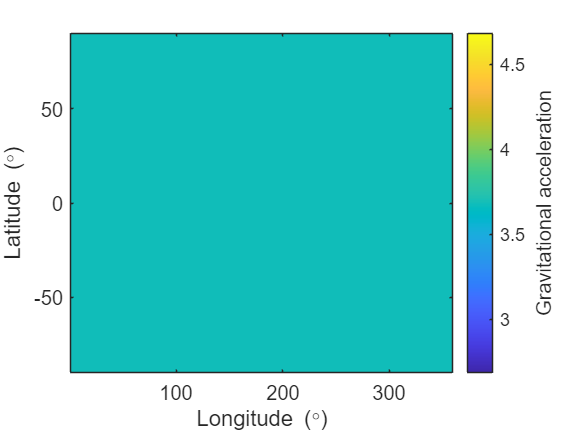

aa=12;
figure
imagesc(lonT,latT,gravity_map);cc=colorbar;
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Gravitational acceleration','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

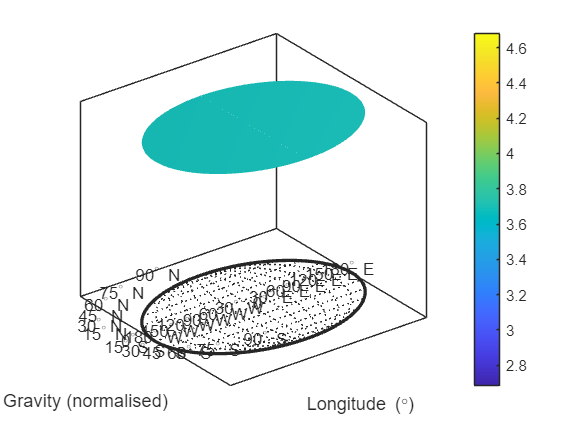


figure
axesm('mollweid', 'Frame', 'on', 'Grid', 'on', 'MeridianLabel', 'on', 'ParallelLabel', 'on')
setm(gca, 'MLabelParallel', 10)
geoshow(LatT, LonT, gravity_map, 'DisplayType', 'surface')
colorbar;
xlabel('Longitude (\circ)')
ylabel('Latitude (\circ)')
ylabel('Gravity (normalised)')
set(gca, 'YDir', 'normal')

light
material(0.6*[1 1 1])
axis normal
view(3)

% Load topography
filename = 'mercury.tif';
% f = fopen(filename,'r','ieee-be');
% topo_map = fread(f,[360*250 Inf],'int16')';
% fclose(f); 

topo_map = imread(filename)

Error using imread>get_full_filename
File "mercury.tif" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);


% Plot topography
figure
imagesc(lonT,latT,topo_map./1e3);cc=colorbar;
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

resized_topo_map = imresize(topo_map, [size(gravity_map, 1), size(gravity_map, 2)]);
resized_topo_map = double(resized_topo_map)

% Calculate bouguer anomaly

rho_crust = 2670
bouguer_anomaly = 2*pi*G*rho_crust*resized_topo_map

% Plot Bouguer anomaly (?)
figure
imagesc(lonT,latT,gravity_map-bouguer_anomaly);cc=colorbar;
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Bouguer Gravity (m/s^2)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

% Flexure
n = 1:size(sc,1);

D = 200e9*(100e3)^3/(12*(1-0.5^2));
PHI = (1 + (D)/(500*2/g_ref).*(2.*(n+1)./(2*R_ref)).^4).^(-1);

sc_flex = zeros(size(sc));

for m = 1:size(sc,2)
    sc_flex(:,m) = sc(:,m).*PHI';
end

sc_flex


mapf = GSHS(sc_flex,lonT,90-latT,179);

figure
imagesc(lonT,latT,mapf./1e3);cc=colorbar;
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

figure
imagesc(lonT,latT,(topo_map-mapf)./1e3);cc=colorbar;
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)